 
data = readtable("diabetes.csv");

% Get the column names (excluding the first column, which might be a label)
columnNames = data.Properties.VariableNames(2:end);

data = [data.Glucose,data.BloodPressure,data.SkinThickness,data.Insulin,data.BMI,data.DiabetesPedigreeFunction,...
        data.Age,data.Outcome];

% Plot the matrix using the specified column names
% plotmatrix(data);
% 
% % Add labels and a title
% xlabel('Variables');
% ylabel('Variables');
% title('Plot Matrix of Diabetes Data');

% Training and Testing Data
All_Data = data;

Xin = All_Data(:,1:end-1);    % Input Features
Yout = All_Data(:,end);        % Output

% Normalize the Data
X = mapminmax(Xin');
Y = mapminmax(Yout', 0,1);

Len=length(Y);

% Training and Testing Data
Prob = 0.8;
NTr = round(Prob*Len);


XTrain = X(:,1:NTr);
YTrain = Y(:,1:NTr);

XTest = X(:, NTr+1:end);
YTest = Y(:, NTr+1:end);

XTest = XTest'; % Features Along Column
YTest=  YTest';

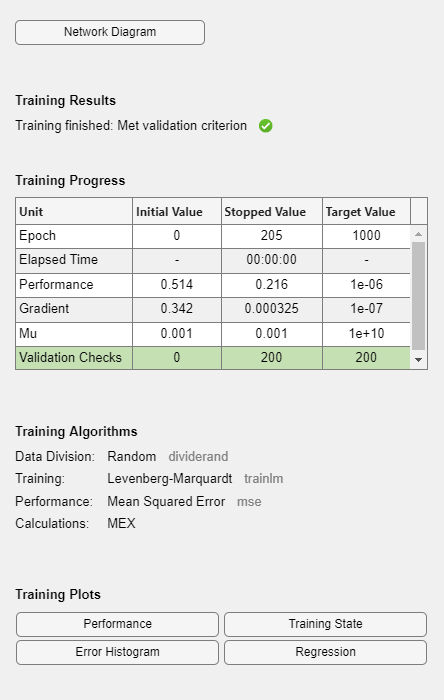

% Set Neural Network Parameters
% Define sizes
[R, C] = size(XTrain);
inputSize = R;

hiddenLayerSize1 = 3;  % Hidden Layer 1
hiddenLayerSize2 = round(R/2);  % Hidden Layer 2

% Define Neural Network
net = feedforwardnet([hiddenLayerSize1, hiddenLayerSize2]);

% Set Training Parameters
net.trainParam.epochs = 1000;  % Maximum number of training epochs
net.trainParam.goal = 1e-6;  % Performance goal
net.trainParam.max_fail = 200;  % Set maximum fail

net.layers{1}.transferFcn = 'tansig';
net.layers{2}.transferFcn = 'tansig';  % Assign transfer function to the second layer
net.layers{3}.transferFcn = 'logsig';  % Assign transfer function to the output layer





net = train(net, XTrain, YTrain) ;




% Generate Simulink Model of Trained Neural Network
gensim (net);



% Extract Weights and Biases
W1d = net.IW{1,1}; % Input Layer
b1d = net.b{1};

W2d = net.LW{2,1}; % Hidden Layer 1
b2d = net.b{2};

W3d = net.LW{3,2}; % Output Layer
b3d = net.b{3};

XTestf=Convert_Data_to_Fixed_Point(X,XTest);


W1df = Convert_Data_to_Fixed_Point(W1d,W1d);
b1df = Convert_Data_to_Fixed_Point(b1d,b1d);

W2df = Convert_Data_to_Fixed_Point(W2d,W2d);
b2df = Convert_Data_to_Fixed_Point(b2d,b2d);

W3df = Convert_Data_to_Fixed_Point(W3d,W3d);
b3df = Convert_Data_to_Fixed_Point(b3d,b3d);

% Save W's and b's in .mat file (for later use)
save('DeepLearing.mat', 'W1d', 'W2d', 'W3d', 'b1d', 'b2d', 'b3d', 'net');

Weight=W1df;
Bias=b1df;
Xw=XTestf';
ytan1 = NN_Layer_Tanh_HDL(Bias,Weight,Xw);
ytan2 = NN_Layer_Tanh_HDL(b2df,W2df,ytan1);
ySig =  NN_Layer_sigmoid_HDL(b3df,W3df,ytan2)

ySig =     0.3838

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 16
        FractionLength: 14

% Get Data From Simulink
%yHDL = out.y1;
ySim = out.y2;

Unable to resolve the name 'out.y2'.

%yNN = out.y3;

% Remove extra sample
%yHDL(end) = [];
ySim(end) = [];
%yNN(end) = [];

% Calculate Accuracies
%Accuracy_HDL = 100*mean(yHDL == YTest);
Accuracy_Sim = 100*mean(ySim == YTest);
%Accuracy_NN = 100*mean(yNN == YTest);